# Chemical Reaction

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

tRange = [0 3];

## Task 2

Y0 = [100; 0];

## Task 3 

The syntax to solve a system of ODEs using `ode45` is the same as the syntax for a single ODE:

`[``tSol``,``YSol``]` `=` `ode45``(``@``odefun``,``tRange``,``Y0``)`

[tSol, YSol] = ode45(@reactionODE, tRange, Y0);

## Task 4

x = YSol(:, 1);

## Task 5

y = YSol(:, 2);

**Visualize *****x***** and *****y***

Do not edit. This code visualizes the solution.

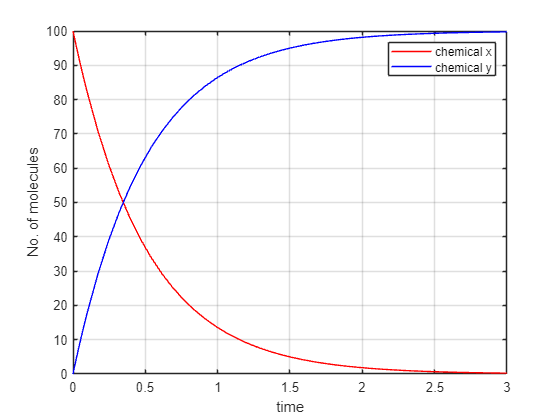

plot(tSol, x, "r")
hold on
grid on
plot(tSol, y, "b")
hold off

% Annotate plot
legend("chemical x", "chemical y")
xlabel("time")
ylabel("No. of molecules")

**ODE function**

Do not edit. This code defines the ODE function for the system of ODEs

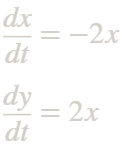

function dYdt = reactionODE(t, Y)
    x = Y(1); % chemical x
    y = Y(2); % chemical y
    dxdt = -2*x;
    dydt = 2*x;
    dYdt = [dxdt; dydt];
end